# PI Controller Design and Experiment

Calculate the gain, poles, and zeros of the controller

% DC Motor Parameters
a = 3.2567;
b = 65.2212;

% Design Requirements
req_Ts = 4 / (a/3)

req_Ts = 3.6847

req_OS = 16;

% Calculate Design Point s_d
sigma = 4/req_Ts;
zeta = - log(req_OS/100) / sqrt(pi^2 + log(req_OS/100)^2);
w_n = sigma/zeta;
w = w_n*sqrt(1-zeta^2);
s_d = -sigma + w*1i

s_d = -1.0856 + 1.8610i


% Evaluate Plant TF at s_d
G_p = zpk([], [-a 0], b)

G_p =
 
    65.221
  -----------
  s (s+3.257)
 
Continuous-time zero/pole/gain model.
Model Properties


G_p_sd = evalfr(G_p, s_d);

% Calculate z_PI
phi_ULG = angle(G_p_sd);
phi_PI = -pi - phi_ULG;
z_PI = sigma + w/tan(phi_PI + angle(s_d))

z_PI = 0.7200


% Evaluate PI Controller TF at s_d
G_c = zpk(-z_PI, 0, 1)

G_c =
 
  (s+0.72)
  --------
     s
 
Continuous-time zero/pole/gain model.
Model Properties


G_c_sd = evalfr(G_c, s_d);

% Evaluate Gain K
K = abs(1/(G_c_sd*G_p_sd))

K = 0.1073

Graph the Root Locus

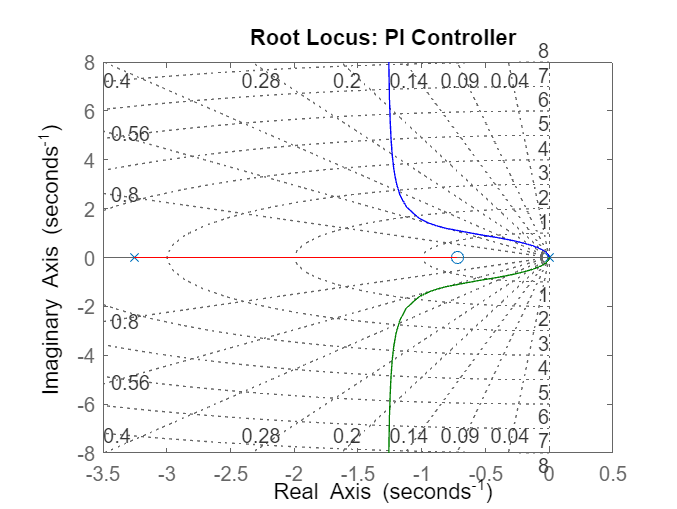

H = zpk([], [], 1); % define the sensor TF
OLTF = G_c*G_p*H; % blocks in cascade

% generate the RL for positive K
rlocus(OLTF); 
title("Root Locus: PI Controller")
sgrid; 

Calculate the Discrete-Time Transfer Function using Tustin's Approximation

Tsamp = 0.01; %s
G_c_z = c2d(G_c,Tsamp,'tustin')

G_c_z =
 
  1.0036 (z-0.9928)
  -----------------
        (z-1)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


Simulate the response

r = pi; % rad

% run the simulation
out = sim('PI_Controller_Discrete', 10);

Evaluate the response

F_v_sim = mean(out.Y.Data(end-10:end)) % calculate final value

F_v_sim = 3.1415


t = out.Y.Time(out.Y.Data <= 0.98*F_v_sim); % calculate times above -2% final value
% t = out.Y.Time(out.Y.Data >= 1.02*F_v_sim); % calculate times above -2% final value

T_s_sim = t(end)

T_s_sim = 3.7000


u0 = out.u.Data(1) % initial input voltage

u0 = 0.3383


SSE = r - F_v_sim % calculate steady state error

SSE = 7.4431e-05


OS_sim = (findpeaks(out.Y.Data) - F_v_sim) / F_v_sim

peak_input = findpeaks(out.u.Data)

Plot the simulated response

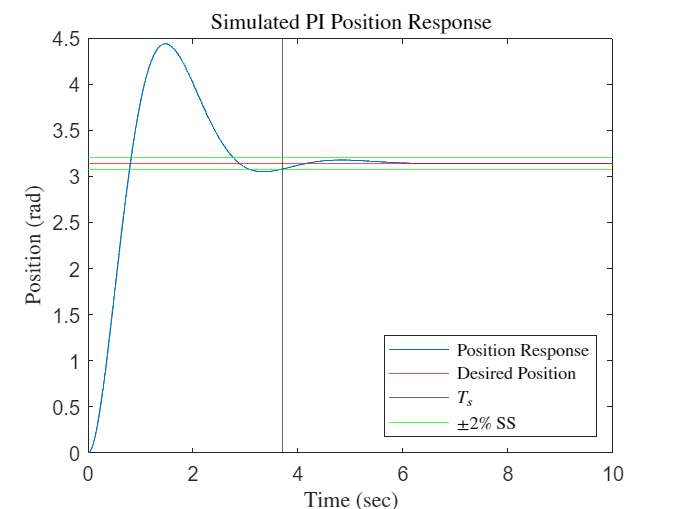

% plot position response
plot(out.Y.Time, out.Y.Data)
yline(r, 'r')
xline(T_s_sim)
yline(F_v_sim * 0.98, 'g')
yline(F_v_sim * 1.02, 'g')
title("Simulated PI Position Response", 'Interpreter','latex')
xlabel("Time (sec)", 'Interpreter','latex')
ylabel("Position (rad)", 'Interpreter','latex')
legend({"Position Response", "Desired Position", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

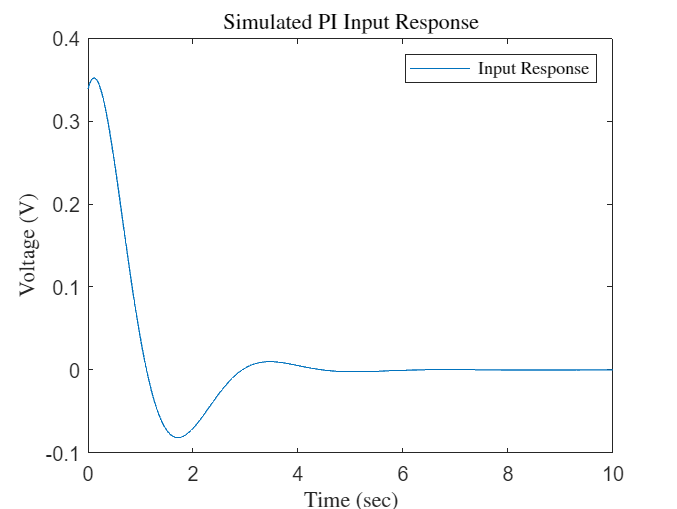


% plot input response
plot(out.u.Time, out.u.Data)
title("Simulated PI Input Response", 'Interpreter','latex')
xlabel("Time (sec)", 'Interpreter','latex')
ylabel("Voltage (V)", 'Interpreter','latex')
legend('Input Response','Interpreter','latex', 'Location','northeast') 

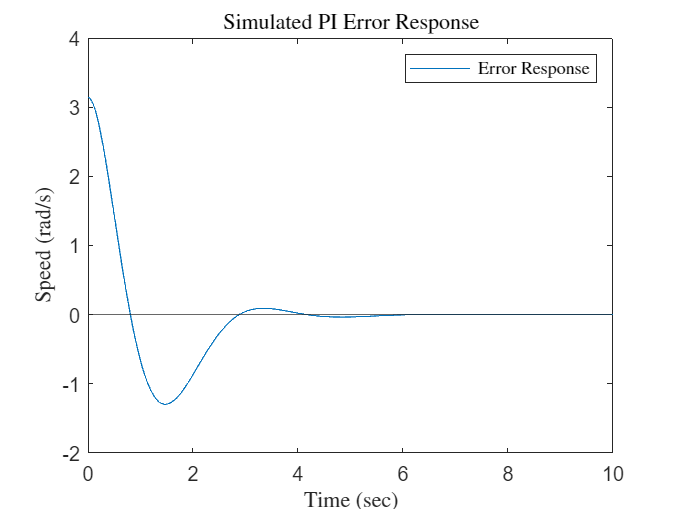


% plot error response
plot(out.e.Time, out.e.Data)
yline(0)
title("Simulated PI Error Response", 'Interpreter','latex')
xlabel("Time (sec)", 'Interpreter','latex')
ylabel("Speed (rad/s)", 'Interpreter','latex')
legend('Error Response','Interpreter','latex', 'Location','northeast') 

Open serial port.

clear s % closes ports already open
s = serialport('COM11',9600) % Check COM#11

Read serial port values and parse data into lists. 

values = 594;
t = zeros(1, values);
pos = zeros(1, values);
spd = zeros(1, values);
inpt = zeros(1, values);
error = zeros(1, values);

% loop through all 
for n = 1:values
    msg = s.readline();
    items = split(msg, ',');
    vals = arrayfun(@str2num, items);
    t(n) = vals(1);
    pos(n) = vals(2);
    spd(n) = vals(3);
    inpt(n) = vals(4);
    error(n) = vals(5);
end

% save PI_2_12032024.mat t pos spd inpt error

Load Trial Data

load PI_2_12032024.mat

Evaluate the response

u0 = inpt(1)

u0 = 0.3383

F_v = mean(pos(end-10:end)) % steady state speed

F_v = 4.5774

SSE = F_v - r

SSE = 1.4358

i = find(pos <= 0.98 * F_v);
T_s = t(i(end))

T_s = 6.3040

OS = (max(pos)-F_v)/F_v

OS = 0

Plot speed, angle and input voltage with respect to time. 

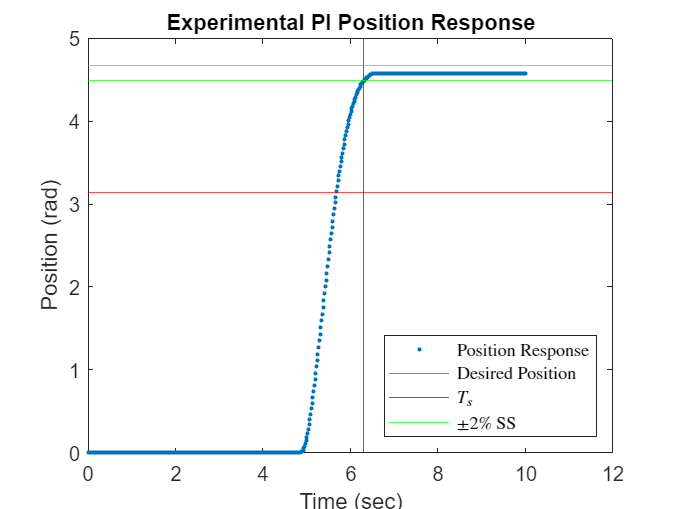

% plot position
plot(t, pos, '.')
yline(r, 'r')
xline(T_s)
yline(F_v * 0.98, 'g')
yline(F_v * 1.02, 'g')
title("Experimental PI Position Response")
xlabel("Time (sec)")
ylabel("Position (rad)")
legend({"Position Response", "Desired Position", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

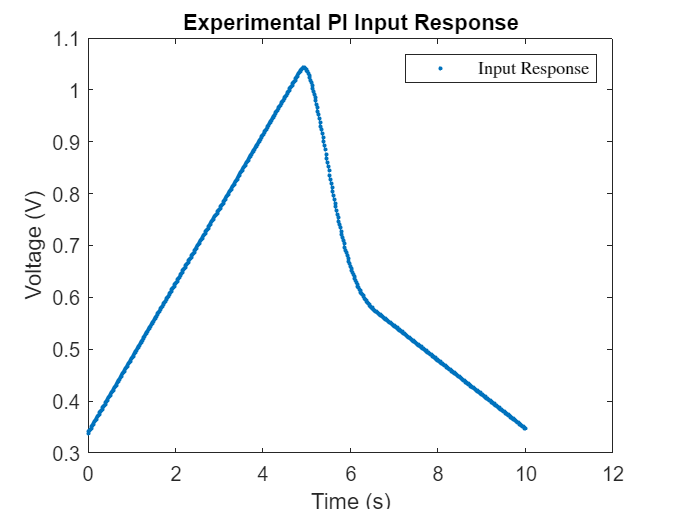


% plot input voltage
plot(t,inpt, '.')
title("Experimental PI Input Response")
xlabel("Time (s)")
ylabel("Voltage (V)")
legend("Input Response", 'Interpreter','latex', 'Location','northeast') 

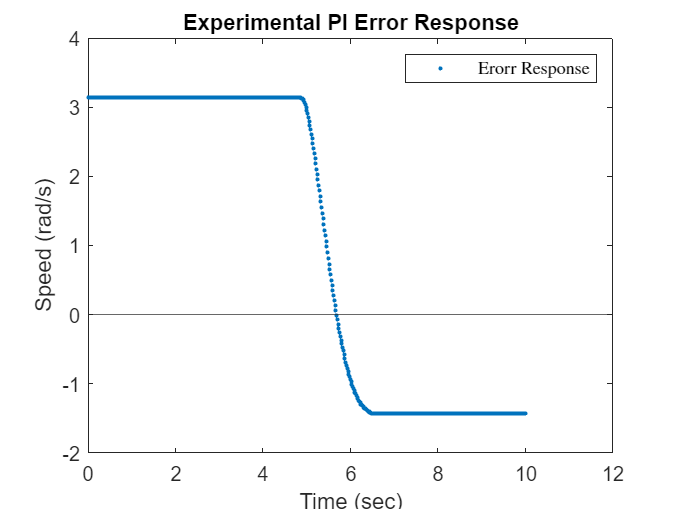


% plot error response
plot(t, error, '.')
yline(0)
title("Experimental PI Error Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")
legend("Erorr Response", 'Interpreter','latex', 'Location','northeast') 

Plot both simulated and experimental position, angle and input voltage with respect to time.

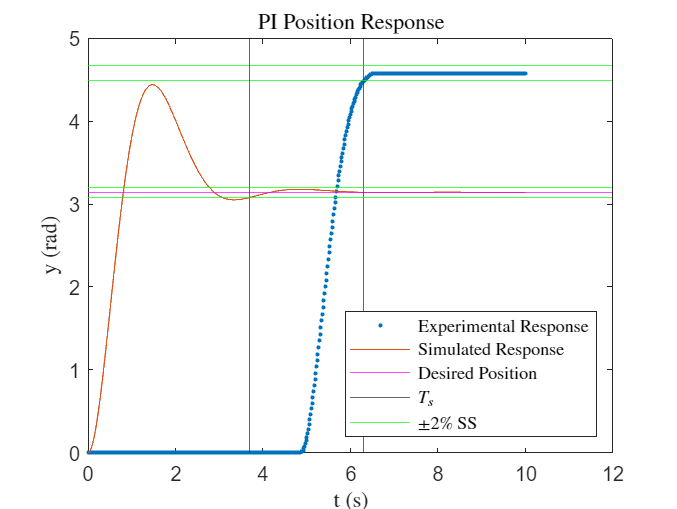

% plot position
plot(t, pos, '.')
hold on 
plot(out.Y.Time, out.Y.Data)
yline(r, 'm')
xline(T_s)
yline(F_v * 0.98, 'g')
yline(F_v * 1.02, 'g')
xline(T_s_sim)
yline(F_v_sim * 0.98, 'g')
yline(F_v_sim * 1.02, 'g')
hold off
title("PI Position Response", 'Interpreter','latex')
xlabel('t (s)', 'Interpreter','latex')
ylabel('y (rad)', 'Interpreter','latex')
legend({"Experimental Response", "Simulated Response", "Desired Position", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

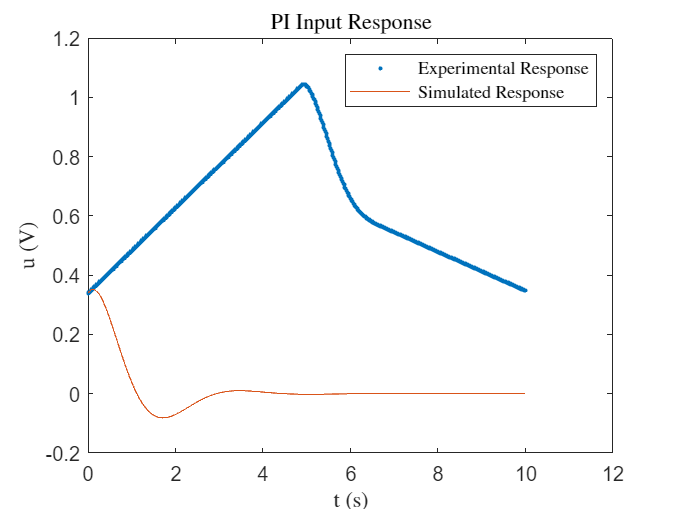


% plot input voltage
plot(t, inpt, '.')
hold on 
plot(out.u.Time, out.u.Data)
hold off
title("PI Input Response", 'Interpreter','latex')
xlabel('t (s)', 'Interpreter','latex')
ylabel('u (V)','Interpreter','latex')
legend({"Experimental Response", "Simulated Response"},'Interpreter','latex', 'Location','northeast') 

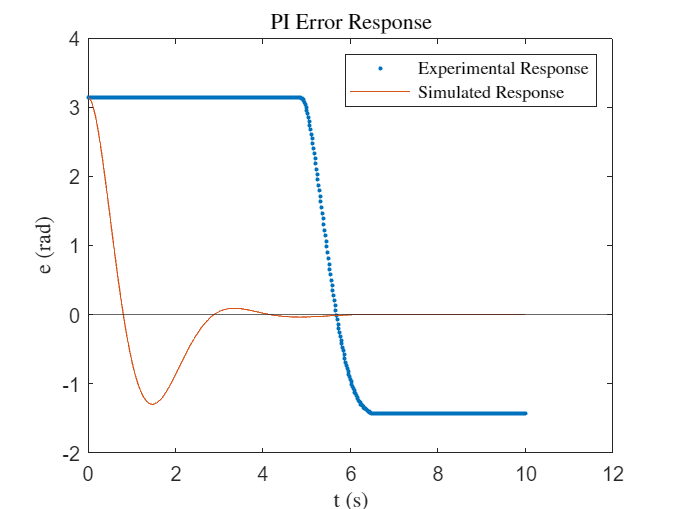


% plot error response
plot(t, error, '.')
hold on
plot(out.e.Time, out.e.Data)
yline(0)
hold off
title("PI Error Response", 'Interpreter','latex')
xlabel('t (s)', 'Interpreter','latex')
ylabel('e (rad)', 'Interpreter','latex')
legend("Experimental Response", "Simulated Response", 'Interpreter','latex', 'Location','northeast') 